### Simulation parameters

This file sets the parameters for all the blocks and variables used in the simulation model.

%% Renewable plant parameters
BatteryStoragePVPlantGFMParameters;% PV and Battery plant parameters
WindFarmGFMControlParameters;% Wind plant parameters
GFLBatteryController.Td=1.5e-3; % Time delay in sec for BESS inverter frequency sensing
Tsim=6.5; %Simulation time

### Configure Wind Turbine MPPT parameters

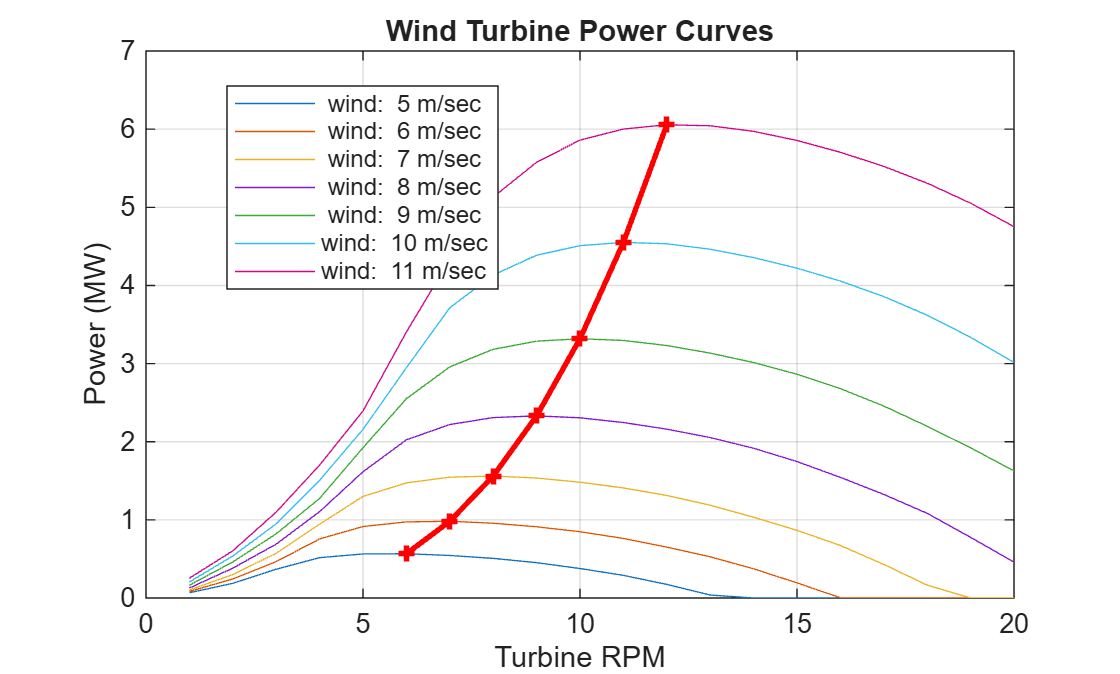

windTurbine.turbineRadius=70; %#ok<*UNRCH> % Turbine radius in meters
%% Generate the wind turbine characteristics by changing the turbine parameters
if false
sweepTurbine;
plotPowerCurves;
mpptPower=maxPower*0.98;
mpptWindSpeed=windSpeedv;
mpptOmega=maxPowerRPM;
windTurbine.turbineRatedPower=max(mpptPower);
else % load pre-generated data for wind turbine
load mpptPower1.mat 
load power21.mat 
load mpptOmega1.mat 
load mpptWindSpeed1.mat
turbineRPMv = 1:20;
windTurbine.turbineRatedPower=max(mpptPower);
plotPowerCurves;
end

### Line and Load Parameters

%% Load & line parameters
time.renewablevariation=Tsim+50;% time to change renewable power
time.loadswitch=Tsim+50;% time to change load power
line.length2=2;% in km
line.length1=21;% in km
loadpq.P=15;%load active power in Mw
loadpq.Q=1e4;%load reactive power VAR
loadstep1=0;% Load switching on
loadstep2=0;% Load switching off

### Set Parameters for Scan

%% Admittance Scan parameters
scan.end=6.5;% time to end frequency scan
scan.start=1.5;% time to start frequency scan
scan.samplingfrequency=5e3;% Sampling frequency of frequency scan
scan.Vd=0.03;% Disturbance voltage magnitude in PU
scan.Vq=0.0;% Disturbance voltage magnitude in PU
scan.Vdc=0.0;% Disturbance voltage magnitude in PU
scan.f=logspace(0,log10(2e3),2e3); % Range of disturbance frequency in Hz
modelorder=4; % Model order to obtain a reduced ordered admittance model of the system
% Copyright 2025 - 2026 The MathWorks, Inc.

Copyright 2025 - 2026 The MathWorks, Inc.